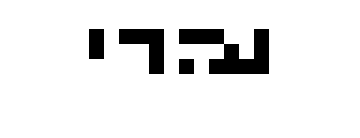

braille = imread('test3.png');
imshow('test3.png', 'InitialMagnification', 1500)


brailleBW = rgb2gray(braille); % to only have 1 dimension
brailleBW(brailleBW==0) = 1; % changes 0 to 1
brailleBW(brailleBW==255) = 0; % changes 255 to 0

[rows, columns] = size(brailleBW); 


%divide matrix into rows of 5 and columns of 3 

c = columns / 2; %finds amount of columns
r = rows / 3; % finds amount of rows

ro = size(brailleBW, 1) / r * ones(1, r); % creats a vector that is the same length as r and adds to rows
co = size(brailleBW, 2) / c * ones(1, c); % creats a vector that is the same length as c and adds to columns

letter = mat2cell(brailleBW, ro, co) % splits image into smaller matrices of each letter

letter = 1×6 cell array
    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}


used the alphabet from this [https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/](https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/) website for the following code.

% make a list of each character in matrix form
A = [1 0; 0 0; 0 0];
B = [1 0; 1 0; 0 0];
C = [1 1; 0 0; 0 0];
D = [1 1; 0 1; 0 0];
E = [1 0; 0 1; 0 0];
F = [1 1; 1 0; 0 0];
G = [1 1; 1 1; 0 0];
H = [1 0; 1 1; 0 0];
I = [0 1; 1 0; 0 0];
J = [0 1; 1 1; 0 0];
K = [1 0; 0 0; 1 0];
L = [1 0; 1 0; 1 0];
M = [1 1; 0 0; 1 0];
N = [1 1; 0 1; 1 0];
O = [1 0; 0 1; 1 0];
P = [1 1; 1 0; 1 0];
Q = [1 1; 1 1; 1 0];
R = [1 0; 1 1; 1 0];
S = [0 1; 1 0; 1 0];
T = [0 1; 1 1; 1 0];
U = [1 0; 0 0; 1 1];
V = [1 0; 1 0; 1 1];
W = [0 1; 1 1; 0 1];
X = [1 1; 0 0; 1 1];
Y = [1 1; 0 1; 1 1];
Z = [1 0; 0 1; 1 1];

 %compare it to the split cells. 
  words = zeros(r,c); %create an array that will store all the numbers corresponding to each letters
 for j = 1:c %for all the columns of letter cell array
    for i = 1:r %for all the rows of letter cell array
        %create an if statement loop that recognises each cell as a letter
        %and then assigns a value from 1:26 corresponding to a letter in the alphabet A being 1 and Z being 26.
        %It then stores that value in the correct position in the words
        %array.
           if letter{i,j} == A; 
               words(i,j) = 1;
           elseif letter{i,j} == B;
                words(i,j) = 2;
           elseif letter{i,j} == C;
                words(i,j) = 3;
           elseif letter{i,j} == D;
                words(i,j) = 4;
           elseif letter{i,j} == E;
                words(i,j) = 5;
           elseif letter{i,j} == F;
                words(i,j) = 6;
           elseif letter{i,j} == G;
                words(i,j) = 7;
           elseif letter{i,j} == H;
                words(i,j) = 8;
           elseif letter{i,j} == I;
                words(i,j) = 9;
           elseif letter{i,j} == J;
                words(i,j) = 10;
           elseif letter{i,j} == K;
                words(i,j) = 11;
           elseif letter{i,j} == L;
                words(i,j) = 12;
           elseif letter{i,j} == M;
                words(i,j) = 13;
           elseif letter{i,j} == N;
                words(i,j) = 14;
           elseif letter{i,j} == O;
                words(i,j) = 15;
            elseif letter{i,j} == P;
                words(i,j) = 16;
            elseif letter{i,j} == Q;
                words(i,j) = 17;
            elseif letter{i,j} == R;
                words(i,j) = 18;
            elseif letter{i,j} == S;
                words(i,j) = 19;
            elseif letter{i,j} == T;
               words(i,j) = 20;
            elseif letter{i,j} == U;
                words(i,j) = 21;
            elseif letter{i,j} == V;
                words(i,j) = 22;
            elseif letter{i,j} == W;
                words(i,j) = 23;
            elseif letter{i,j} == X;
                words(i,j) = 24;
           elseif  letter{i,j} == Y;
                words(i,j) = 25;
           else letter{i,j} == Z;
                words(i,j) = 26;
       
            end
     end
 end

% a voice read them off